d) Decide upon performance specifications for balancing, e.g., frequency of oscillations after a disturbance, decay rate of oscillations for disturbance rejection, i.e., θ → 0. Explain how you chose your specifications and why they are reasonable.

clear all; 
close all;
syms s l g Kp Ki Jp Ji Ci   % define symbolic variables

**Frequency of oscillations**

This is the imaginary portion

omega_n = 4.5080; % natural frequency
omega_chosen = omega_n + 0.5; % oscillate quickly > oscillate slowly

eval_dist = -1; % two poles: evaldist +- omega_chosen*i

**Decay rate of oscillations**

NOTE: it's a third order system, so we have one pole that lands on the real axis

We don't want an overdamped system - we want an underdamped, since it's going to get close faster although it will get close slower.

eval_dist_long = -15; % the real portion

**Rocky_closed_loop_poles.m**

% 1) Symbolically calculates closed loop transfer function of PI disturbannce
% rejection control system for Rocky. 
% Currently no motor model (M =1).Placeholder for motor model (1st order TF)
%
% 2) Specify location of (target)poles based on desired reponse. The number of
% poles = denominator polynomial of closed loop TF
%
% 3) Extract the closed loop denomiator poly and set = polynomial of target
% poles
%
% 4) Solve for Ki and Kp to match coefficients of polynomials. In general,
% this will be underdefined and will not be able to place poles in exact
% locations. 
%
% 5) Plot impulse response to see closed-loop behavior. 
%
% based on code by SG. last modified 3/12/21 CL

% calculated values
tau = 0.103;
k = 2.439;

Hvtheta = (-s/l) / (s^2-(g/l));     % TF from velocity to angle of pendulum

K = Kp + (Ki/s);                    % TF of the PI angle controller
M = (k/tau) / (s+(1/tau));          % TF of motor 
%  
%closed loop transfer function from disturbance d(t)totheta(t)
Hcloop = 1/(1-Hvtheta*M*K)  

$$Hcloop = -\frac{1}{\frac{2439\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{103\,l\,\left(\frac{g}{l}-s^{2}\right)\,\left(s+\frac{1000}{103}\right)}-1}$$


pretty(simplify(Hcloop))       % to display the total transfer function

                                        2
                   (103 s + 1000) (- l s  + g)
- -------------------------------------------------------------
                                                   2          3
  2439 Ki - 1000 g + 2439 Kp s - 103 g s + 1000 l s  + 103 l s




% Substitute parameters and solve
% system parameters
g = 9.81;
l = 0.4822; %effective length

Hcloop_sub = subs(Hcloop) % sub parameter values into Hcloop

$$Hcloop\_sub = \frac{1}{\frac{12195000\,s\,\left(\mathrm{Kp}+\frac{\mathrm{Ki}}{s}\right)}{248333\,\left(s^{2}-\frac{49050}{2411}\right)\,\left(s+\frac{1000}{103}\right)}+1}$$


% specify locations of the target poles,
% choose # based on order of Htot denominator
% e.g., want some oscillations, want fast decay, etc.

p1 = eval_dist + (omega_chosen*i)

p1 = -1.0000 + 5.0080i

p2 = eval_dist - (omega_chosen*i)

p2 = -1.0000 - 5.0080i

p3 = eval_dist_long

p3 = -15


% target characteristic polynomial
% if motor model (TF) is added, order of polynomial will increases
tgt_char_poly = (s-p1)*(s-p2)*(s-p3);

% get the denominator from Hcloop_sub
[n d] = numden(Hcloop_sub);

% find the coefficients of the denominator polynomial TF
coeffs_denom = coeffs(d, s);

% divide though the coefficient of the highest power term
coeffs_denom = coeffs_denom/(coeffs_denom(end));

% find coefficients of the target charecteristic polynomial
coeffs_tgt = coeffs(tgt_char_poly, s);

% solve the system of equations setting the coefficients of the
% polynomial in the target to the actual polynomials
solutions = solve(coeffs_denom(1:2) == coeffs_tgt(1:2),  Kp, Ki);

% display the solutions as double precision numbers
Kp = double(solutions.Kp)

Kp = 1.5563

Ki = double(solutions.Ki)

Ki = 11.9884


% Location of the poles of the closed-loop TF.
% NOTE there are only 2 unknowns but 3 polynomial coefficients so 
% the problem is underdetermined and the closed loop poles don't exact
% match the target poles. 
% use trial-and-error to tune response
closed_loop_poles = vpa(roots(subs(coeffs_denom)), 5)

$$closed\_loop\_poles = \left(\begin{array}{c} -0.11741\\ -0.012972-0.14698\,\mathrm{i}\\ -0.012972+0.14698\,\mathrm{i} \end{array}\right)$$


% Plot impulse response of closed-loop system
    TFstring = char(subs(Hcloop));
    % Define 's' as transfer function variable
    s = tf('s');
    % Evaluate the expression
    eval(['TFH = ',TFstring]);

TFH =
 
  1.398e20 s^4 + 1.357e21 s^3 - 2.844e21 s^2 - 2.761e22 s
  -------------------------------------------------------
  1.398e20 s^4 + 1.357e21 s^3 + 7.84e21 s^2 + 5.469e22 s
 
Continuous-time transfer function.



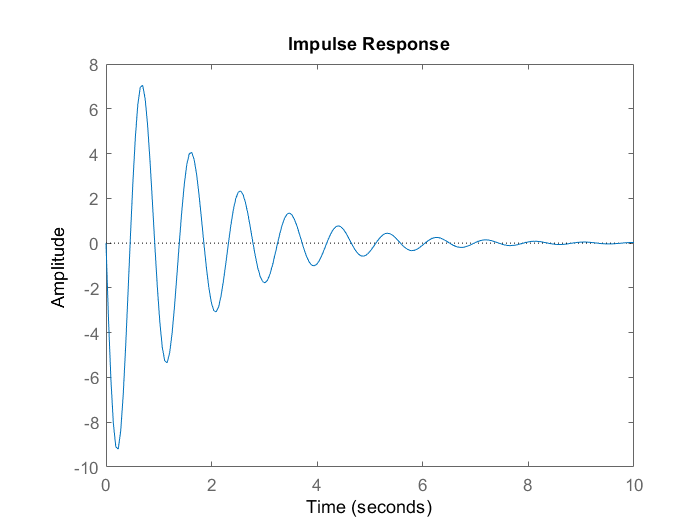

    figure (1)
    impulse(TFH);   %plot the impulse reponse

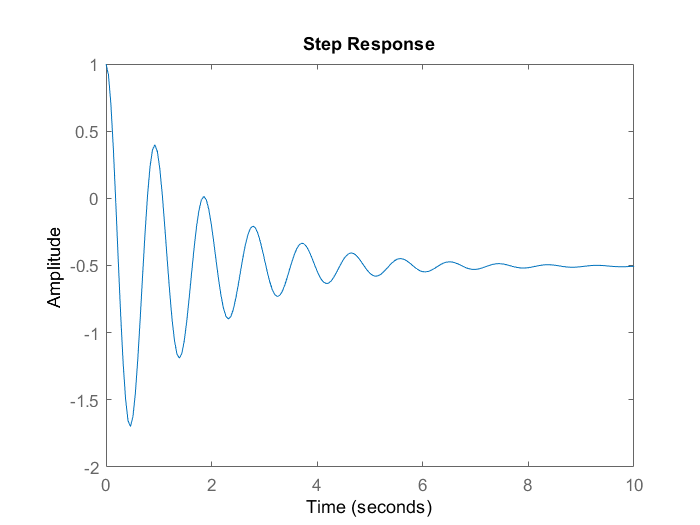

    figure(2)
    step(TFH)

    pole(TFH)

ans =    0.0000 + 0.0000i
  -8.5171 + 0.0000i
  -0.5958 + 6.7510i
  -0.5958 - 6.7510i


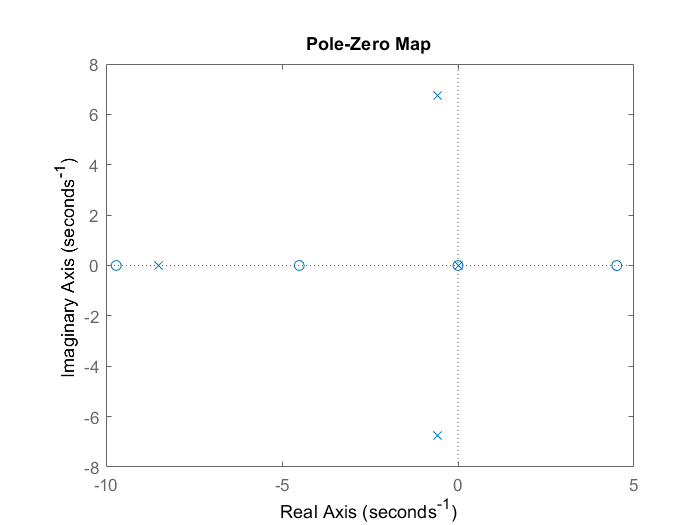

    pzplot(TFH)

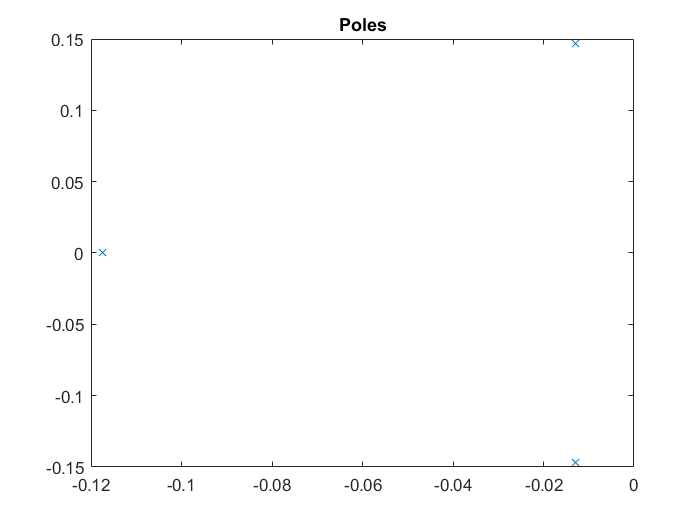


% Plot closed loop poles
figure()
plot(real(closed_loop_poles), imag(closed_loop_poles), 'x')
title("Poles")